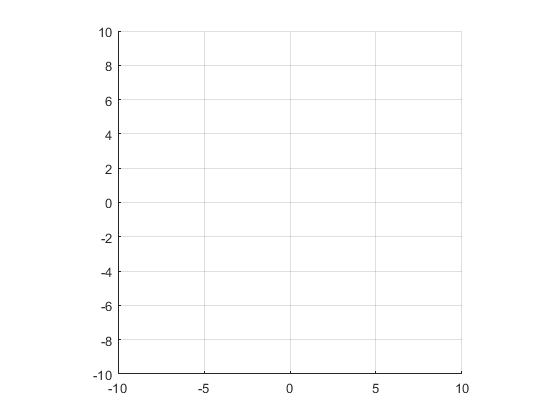


close all
a = polyshape(circle.xdata,circle.ydata);
x = [1 0];
y = [0 1];
trans = zeros(3,2);
random = randi([-10,10],4,1);
ac = [random(1), random(2)];
b = [random(3),random(4)];
for i = linspace(0,3,100)
    v =   ac*i;
    f = translate(a, v+b); % agregar velocidad y un punto de inicio aleatorio
    % detectar colisiones
    for j =1:3
        trans(j,:) = [dot(x,f.Vertices(j,:)), dot(y,f.Vertices(j,:))];
    end
    p1min = min(trans);
    p1max = max(trans);
    if p1min(1,1) < -10 || p1max(1,1) > 10
        title('Collision with x axis')
        ac_aft = [-ac(1),ac(2)];
        v = ac_aft*i;
    elseif p1min(1,2) < -10 || p1max(1,2) > 10
        title('Colision with y axis')
        ac_aft = [ac(1),-ac(2)];
        v = ac_aft*i;
    end
    drawnow
    plot(f);
    axis equal
    xlim([-10,10]);
    ylim([-10,10]);
    grid on

end


b = 1